# Monte Carlo Simulation

Estimate probability that a randomly thrown dart on a square will land in the inscribed circle. In this simulation, we assume that the square has a side of length 2, such that the radius of the inscribed circle is 1. 

N = 10000

N = 10000

 
NumSuccess = 0;
samples = table( zeros(N,1),zeros(N,1),zeros(N,1), 'VariableNames', { 'x' , 'y' , 'sucess'});
for i=1:N
    x = rand()*2; % Draw a random number x between 0..2
    y = rand()*2; % Draw a random number y between 0..2
    samples.x( i ) = x;
    samples.y( i ) = y;
    d = sqrt( (x-1)^2 + (y-1)^2 ); % Calculate distance from (x,y) towards (1,1), the center of the square
    if (d<=1)  % If distance is smaller than 1, we land in the circle
        NumSuccess = NumSuccess + 1; % Increment counter for number of successes
        samples.success( i ) = 1;
    else
        samples.success( i ) = 0;
    end
end
EstProb = NumSuccess / N; % Calculate probability of success
fprintf( 'Estimated probability: %3.3f\n' , EstProb);

Estimated probability: 0.787


fprintf( 'Estimated probability * 4: %3.3f\n' , EstProb * 4);

Estimated probability * 4: 3.147


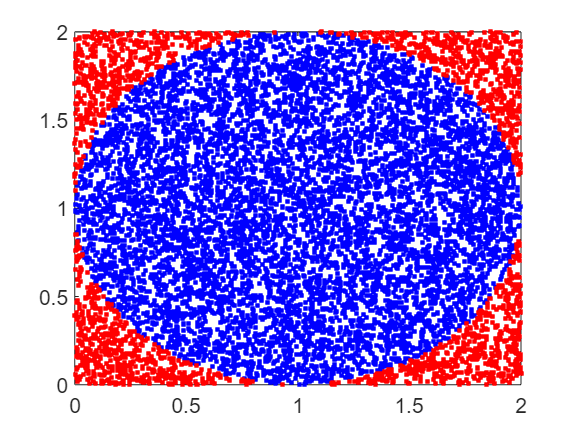


% Create figure
figure( 1 ); clf;
% Plot the (x,y) samples that fell within the circle
plot( samples.x( samples.success==1 ) , samples.y( samples.success==1 ) , 'b.'); 
hold on;
% Plot the (x,y) samples that fell outside the circle
plot( samples.x( samples.success==0 ) , samples.y( samples.success==0 ) , 'r.');